## Intro

This is a testbench for processing both the OpenMic-2018 and IRMAS data sets for musical instrument identification, with the goal of testing different feature extraction and modeling algorithms. The methods below follow a paper titled "Audio Signal Classification Based on Optimal Wavelet and Support Vector Machine" (https://ieeexplore.ieee.org/abstract/document/4426756). The purpose of this script is to try out one data file at a time, with the plans to 

## Signal Capture

For this project, we are obtaining our signal data from the IRMAS database. This script will focus on training data for now. A testing script will be put together later in the project development phase.

## Import testing data

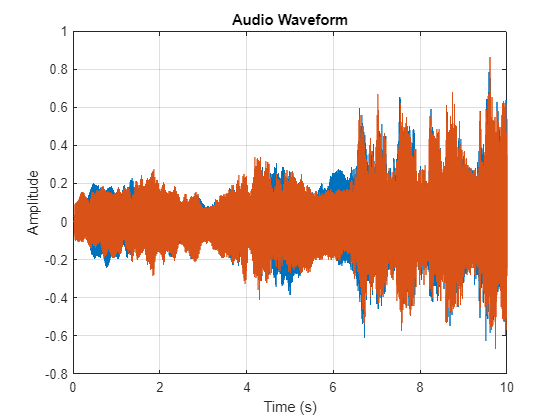

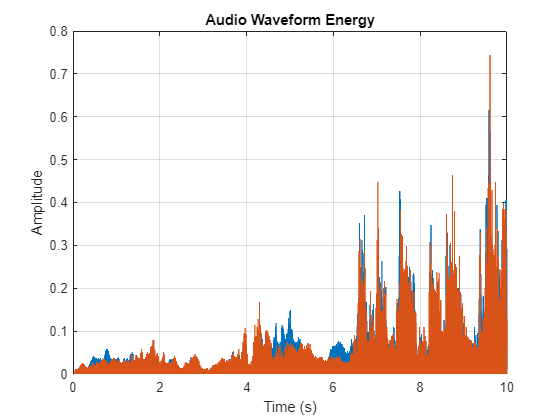

importMode = "ReadAudioFiles"; % Save time by reusing workspace variables
plotsEnabled = true;
testmode = "Single File";
useMatlabFeatExtract = true;
channelMode = "left";
database = "OpenMic-2018";
if(testmode=="Single File")
    % Single file test
    if(database=="IRMAS")
        file_path = '.\IRMAS-TrainingData\pia\[pia][cla]1283__1.wav';
    else
        % file_path = '.\openmic-2018\audio\000\000135_483840.ogg';
        file_path = '.\openmic-2018\audio\000\000046_3840.ogg';
    end

    if(importMode=="ReadAudioFiles")
        % Read the audio data from the .ogg/.wav file
        [audio_data, sample_rate] = audioread(file_path);
        audio_data_energy = audio_data.*audio_data;
        % Duration of the audio in seconds
        audio_duration = length(audio_data) / sample_rate;
    end

    % Plot the audio waveform
    if(plotsEnabled==true)
        t = (0:(length(audio_data) - 1)) / sample_rate; % Time vector
        figure;
        plot(t, audio_data);
        xlabel('Time (s)');
        ylabel('Amplitude');
        title('Audio Waveform');
        grid on;

        t = (0:(length(audio_data_energy) - 1)) / sample_rate; % Time vector
        figure;
        plot(t, audio_data_energy);
        xlabel('Time (s)');
        ylabel('Amplitude');
        title('Audio Waveform Energy');
        grid on;
    end
    
    % For easier processing we vectorize the stereo data. Converting to
    % mono could possibly distort or remove information we need.
    switch(channelMode)
        case 'mono'
            audio_data_vectorized = mean(audio_data,2);
        case 'stereo'
            audio_data_vectorized = reshape(audio_data(:, :, 1), [], 1);
        case 'left'
            audio_data_vectorized = audio_data(:,1);
        case 'right'
            audio_data_vectorized = audio_data(:,2);
    
    
    end
elseif(testmode=="Full Directory")
    % Full directory test
    if(database=="IRMAS")
        dir_path = '.\IRMAS-TrainingData\pia\';
    else
        dir_path = '.\openmic-2018\audio\000\';
    end

    if(importMode=="ReadAudioFiles")
       files = dir(dir_path);
       
       struct
       % Import all audio files
       for i = 1:length(files)
           if ~files(i).isdir && endsWith(files(i).name,{'.ogg','.wav'})
            files(i).name
           end
    
       end
    end

elseif(testmode=="All Files")

end

## Data Conditioning

Data has to be prepared before we perform feature extraction. This process follows three steps per the paper referenced in the Intro:

- Frame Forming

- Pre-emphasized Filter

- Energy of frames and Threshold

### Frame Forming

This process will take the audio data and break it into frames. Per the paper we are following, the frames should be 512 samples with an overlap of 75%.

% Parameters
% doFrameForming=true; % Useful when audio clips are long
frameLength = 512;
frameOverlap = 0.75;
frameOverlapInSamps = floor(frameLength*frameOverlap);
sampIncrement = frameLength - frameOverlapInSamps;

% Frame forming 
if(~useMatlabFeatExtract)  
    % It's possible that the audio data won't evenly divide into frames
    % with a length of 512. Before framing, we calculate the number of
    % frames needed, and then zero pad that last one.
    framesPerVector = length(audio_data_vectorized)/frameLength; % Assumes no overlap
    numFrames=ceil(framesPerVector/(1-frameOverlap)); % Accounts for overlap
    framed_audio = zeros(frameLength,numFrames);
    
    % Populate the frames into matrix
    k = 1;
    currSample = 1;
    while(k<=numFrames)
        try
            framed_audio(:,k) = audio_data_vectorized(currSample:currSample+frameLength-1);
        catch
            numMissingSamps = frameLength - length(audio_data_vectorized(currSample:end));
            zeroPaddedFrame = zeros(numMissingSamps,1);
            framed_audio(:,k) = [audio_data_vectorized(currSample:end);zeroPaddedFrame];
        end
        currSample = currSample+sampIncrement;
        k=k+1;
    end
    
    if(plotsEnabled==true)
        framed_audio_stage_0 = reshape(framed_audio(:, :, 1), [], 1); % For data visualization
    end
end

### Pre-Emphasized Filtering

For some audio, there may be minimal high-frequency components that come from the musician or instrument. These components have really low amplitude, but can be useful information for identifying an instrument. We can filter to augment the energy at the higher frequencies. Equations 1,2, and 3 from the paper are implemented below. **TODO**: The paper assumes zero indexing, whereas matlab is 1 indexing. Verify that this won't cause issues.

% Pre-emphasized filtering

if(~useMatlabFeatExtract)
    % Implementation of equation 1 - pre-emphasized filter
    for k=1:numFrames
        % Note that s0, or the first sample framed_audio(1,k), is left as-is
        for n=2:frameLength 
            framed_audio(n,k) = framed_audio(n,k)-(0.96*framed_audio(n-1,k));
        end
    end
    
    % Implementation of equation 3 - Hamming window definition
    h = 0:frameLength-1;
    h = (0.54)-(0.46.*cos(2*pi*h/511));
    
    % Implementation of equation 2 - Hamming window filter
    for k=1:numFrames
        for n=1:frameLength 
            framed_audio(n,k) = framed_audio(n,k)*h(n);
        end
    end
    
    if(plotsEnabled==true)
        framed_audio_stage_1 = reshape(framed_audio(:, :, 1), [], 1); % For data visualization
    end
end

### Energy of frames and Threshold

Equation 4 in the paper is used to separate silent and non-silent frames. This is done by checking that the audio is above a certain threshold. The paper does not go into details as to how this value was selected, but since it was used on the IRMAS data we should keep it to replicate results.

if(~useMatlabFeatExtract)
    energyThreshold = 0.5e-3; % Set to 400 in the paper, but won't work for our code since it appears normalized
    numNonSilentFrames=0;
    nonSilentFramedAudio=[];
    for k=1:numFrames
        frameEnergy = sum(framed_audio(:,k).*framed_audio(:,k));
        if(frameEnergy>energyThreshold)
            nonSilentFramedAudio=[nonSilentFramedAudio,framed_audio(:,k)];
            numNonSilentFrames=numNonSilentFrames+1;
        end
    end
    
    if(plotsEnabled==true)
        framed_audio_stage_2 = reshape(nonSilentFramedAudio(:, :, 1), [], 1); % For data visualization
    end
end

### Resulting Preprocessed Data

if(~useMatlabFeatExtract)
    % Vectorize the remaining data
    VectorizedNonSilentFramedAudio = reshape(nonSilentFramedAudio(:, :, 1), [], 1); % For data visualization
    
    % Plot the preprocessed audio waveform
    if(plotsEnabled==true)
        t = (0:(length(audio_data_vectorized) - 1)) / sample_rate; % Time vector
        figure;
        subplot(1,2,1);
        plot(t, audio_data_vectorized);
        xlabel('Time (s)');
        ylabel('Amplitude');
        title('Original Vectorized Audio Waveform');
        grid on;
    
        t = (0:(length(VectorizedNonSilentFramedAudio) - 1)) / sample_rate; % Time vector
        % figure;
        subplot(1,2,2);
        plot(t, VectorizedNonSilentFramedAudio);
        xlabel('Time (s)');
        ylabel('Amplitude');
        title(sprintf('Preprocessed Vectorized Audio Waveform'));
        grid on;
    end
end

## Feature Extraction

This section is intended to have a variety of feature extractions to try out. The paper goes through the following types of features:

- Wavelet Tranform based

- Fourier Transform based

- Time-domain based

### Wavelet Tranform based Features (Not currently implemented)

Most features attemped in the paper utilize the wavelet transform. 

% Define the wavelets
% psi

### Audio Feature Extraction Matlab Function

The audioFeatureExtractor() function allows us to pick and choose various features to try out.

aFE = audioFeatureExtractor(...
    SampleRate=sample_rate, ...
    Window=hamming(round(0.03*sample_rate),"periodic"), ...
    OverlapLength=round(frameOverlapInSamps/sample_rate), ...
    pitch=false,...
    shortTimeEnergy=true,...
    zerocrossrate=true);

features = extract(aFE,audio_data_vectorized);

figure;
title('Zero Cross Rate')
plot(features(:,1));

figure;
title('Short Time Energy')
plot(features(:,2));

figure;
scatter(features(:,1),features(:,2))
title('Two-Feature Comparison')
xlabel('Zero Cross Rate');
ylabel('Short Time Energy');


## Modeling and Prediction